Importing the data

data = readtable("Roaddata.csv")

data = 1000×14 table
       date       time    A_B    A_C    A_D    B_A    B_C    B_D    C_A    C_B    C_D    D_A    D_B    D_C
    __________    ____    ___    ___    ___    ___    ___    ___    ___    ___    ___    ___    ___    ___

    0001-01-21      0     18     19     24      9      8     25     12     15     15     16     10     16 
    0002-01-21      1     15     21     12     16     13     10     12     13     11     12     17     13 
    0003-01-21      2     13      8     14     16     16     17      7    

% Display the first few rows of the data
head(data)

ans = 8×14 table
       date       time    A_B    A_C    A_D    B_A    B_C    B_D    C_A    C_B    C_D    D_A    D_B    D_C
    __________    ____    ___    ___    ___    ___    ___    ___    ___    ___    ___    ___    ___    ___

    0001-01-21     0      18     19     24      9      8     25     12     15     15     16     10     16 
    0002-01-21     1      15     21     12     16     13     10     12     13     11     12     17     13 
    0003-01-21     2      13      8     14     16     16     17      7     13 


% Display summary statistics of the data
summary(data)

Variables:

    date: 1000×1 datetime

        Properties:
            Description:  date
        Values:

            Min       0001-01-21
            Median    0016-02-22
            Max       0031-12-22

    time: 1000×1 double

        Properties:
            Description:  time
        Values:

            Min           0   
            Median       11   
            Max          23   

    A_B: 1000×1 double

        Properties:
            Description:  A-B
        Values:

            Min           3   
            Median       11   
            Max          19   

    A_C: 1000×1 double

        Properties:
            Description:  A-C
        Values:

            Min           6   
            Median       15   
            Max          24   

    A_D: 1000×1 double

        Properties:
            Description:  A-D
        Values:

            Min          11   
            Median       23  

% Check for missing values
missingValues = sum(ismissing(data));

% Display the number of missing values per column
disp('Number of missing values per column:');

Number of missing values per column:


disp(missingValues);

  Columns 1 through 8

     0     0     0     0     0     0     0     0

  Columns 9 through 14

     0     0     0     0     0     0




% Remove rows with missing values
data = rmmissing(data);



% Extract numeric columns for normalization
numericData = data{:, 3:end};

% Normalize the data (example: min-max normalization)
normalizedData = (numericData - min(numericData)) ./ (max(numericData) - min(numericData));

% Replace original numeric columns with normalized data
data{:, 3:end} = normalizedData;



% Save the preprocessed data to a new CSV file
writetable(data, 'preprocessed_traffic_data.csv');

% Calculate mean, median, and standard deviation for each route
routeNames = data.Properties.VariableNames(3:end); % Exclude date and time columns

% Initialize arrays to store statistics
means = zeros(1, length(routeNames));
medians = zeros(1, length(routeNames));
stdDevs = zeros(1, length(routeNames));

% Calculate statistics for each route
for i = 1:length(routeNames)
    means(i) = mean(data{:, routeNames{i}});
    medians(i) = median(data{:, routeNames{i}});
    stdDevs(i) = std(data{:, routeNames{i}});
end

% Display statistics
statsTable = table(routeNames', means', medians', stdDevs', ...
    'VariableNames', {'Route', 'Mean', 'Median', 'StandardDeviation'})

statsTable = 12×4 table
     Route      Mean      Median     StandardDeviation
    _______    _______    _______    _________________

    {'A_B'}    0.50487        0.5         0.30544     
    {'A_C'}    0.49489        0.5         0.29936     
    {'A_D'}    0.51461    0.52174         0.29734     
    {'B_A'}    0.50356        0.5         0.30654     
    {'B_C'}    0.50481        0.5         0.30252     
    {'B_D'}     0.5011        0.5         0.30393     
    {'C_A'}    0.49056        0.5         0.30204     
    {'C_B'}    0.49619        0.5         0.30549     
    {'C_D'}      0.504        0.5         0.30085     
    {'D_A'}    0.50496    0.52174         0.30298     
    {'D_B'}     0.5117        0.5         0.29853     
    {'D_C'}    0.51362        0.5         0.30804     


% Calculate total traffic volume for each time of day
trafficByTime = groupsummary(data, 'time', 'sum', routeNames);

% Identify peak hours (hours with the highest total traffic)
[~, peakHourIdx] = max(trafficByTime{:, 3:end}, [], 1);
peakHours = trafficByTime.time(peakHourIdx);

% Display peak hours
peakHoursTable = table(routeNames', peakHours, ...
    'VariableNames', {'Route', 'PeakHour'})

peakHoursTable = 12×2 table
     Route     PeakHour
    _______    ________

    {'A_B'}        1   
    {'A_C'}        0   
    {'A_D'}        8   
    {'B_A'}        1   
    {'B_C'}       10   
    {'B_D'}       14   
    {'C_A'}        5   
    {'C_B'}       22   
    {'C_D'}       12   
    {'D_A'}        1   
    {'D_B'}       23   
    {'D_C'}        1   


% Calculate correlation matrix for traffic flows
correlationMatrix = corr(data{:, 3:end});

% Display correlation matrix
corrTable = array2table(correlationMatrix, ...
    'VariableNames', routeNames, 'RowNames', routeNames)

corrTable = 12×12 table
              A_B            A_C           A_D           B_A          B_C           B_D           C_A          C_B           C_D           D_A           D_B           D_C    
           __________    ___________    __________    _________    __________    __________    _________    __________    _________    ___________    __________    __________

    A_B             1       0.024752    -0.0044389     0.035311      0.053657      0.024237    -0.051867    -0.0078044    0.0034044       0.036069    -0.0099228    -0.0029508
    A_C 

% Load the dataset
trafficData = readtable('Roaddata.csv'); 

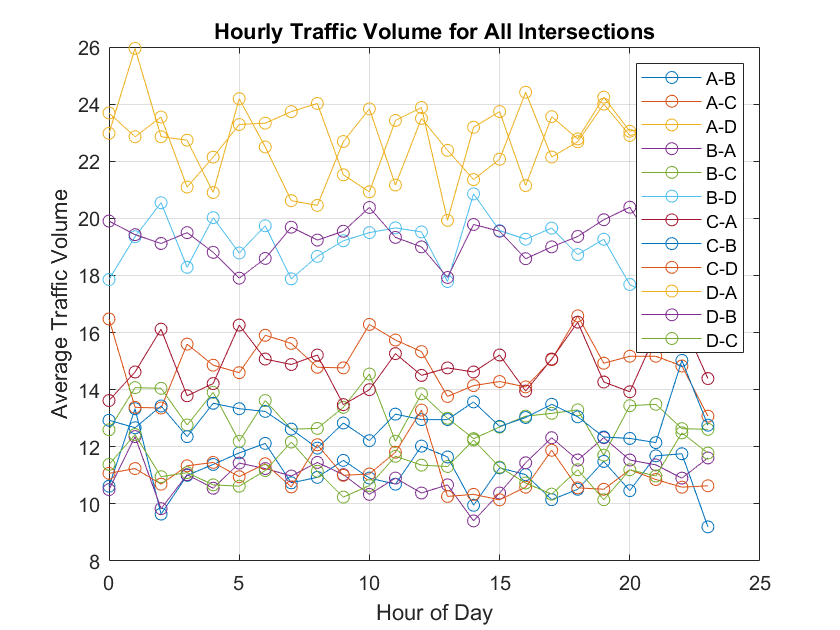


% Aggregate data by hour
hourlyData = varfun(@mean, trafficData, 'InputVariables', {'A_B', 'A_C', 'A_D', 'B_A', 'B_C', 'B_D', 'C_A', 'C_B', 'C_D', 'D_A', 'D_B', 'D_C'}, 'GroupingVariables', 'time');

% Extract time and mean values for each route
time = hourlyData.time;
mean_A_B = hourlyData.mean_A_B;
mean_A_C = hourlyData.mean_A_C;
mean_A_D = hourlyData.mean_A_D;
mean_B_A = hourlyData.mean_B_A;
mean_B_C = hourlyData.mean_B_C;
mean_B_D = hourlyData.mean_B_D;
mean_C_A = hourlyData.mean_C_A;
mean_C_B = hourlyData.mean_C_B;
mean_C_D = hourlyData.mean_C_D;
mean_D_A = hourlyData.mean_D_A;
mean_D_B = hourlyData.mean_D_B;
mean_D_C = hourlyData.mean_D_C;

% Plot aggregated data
figure;
plot(time, mean_A_B, '-o', 'DisplayName', 'A-B');
hold on;
plot(time, mean_A_C, '-o', 'DisplayName', 'A-C');
plot(time, mean_A_D, '-o', 'DisplayName', 'A-D');
plot(time, mean_B_A, '-o', 'DisplayName', 'B-A');
plot(time, mean_B_C, '-o', 'DisplayName', 'B-C');
plot(time, mean_B_D, '-o', 'DisplayName', 'B-D');
plot(time, mean_C_A, '-o', 'DisplayName', 'C-A');
plot(time, mean_C_B, '-o', 'DisplayName', 'C-B');
plot(time, mean_C_D, '-o', 'DisplayName', 'C-D');
plot(time, mean_D_A, '-o', 'DisplayName', 'D-A');
plot(time, mean_D_B, '-o', 'DisplayName', 'D-B');
plot(time, mean_D_C, '-o', 'DisplayName', 'D-C');
hold off;

% Add labels and title
xlabel('Hour of Day');
ylabel('Average Traffic Volume');
title('Hourly Traffic Volume for All Intersections');
legend('show');

% Improve plot appearance
grid on;

% Main simulation script
% Set simulation parameters
simulationTime = 300; % 5 minutes in seconds
timeStep = 0.1; % Time step in seconds
currentTime = 0;


% Create scenario and get spawn points
[scenario, spawnPoints] = createDrivingScenario();

% Initialize data storage
vehicleData = [];
vehicleID = 0;

% Main simulation loop
while currentTime < simulationTime
    % Spawn vehicles probabilistically
    if rand < 0.1 % Example probability
        vehicleID = vehicleID + 1;
        spawnVehicle(scenario, vehicleID, spawnPoints);
    end
    
    % Update vehicle movements
    updateVehicleMovements(scenario, currentTime);
    
    % Update traffic lights
    updateTrafficLights(scenario, currentTime);
    
    % Record sensor data
    vehicleData = recordSensorData(scenario, vehicleData, currentTime);
    
    % Advance scenario simulation
    advance(scenario, timeStep);
    
    % Increment time
    currentTime = currentTime + timeStep;
end

Unrecognized function or variable 'recordSensorData'.


% Export data to CSV
exportDataToCSV(vehicleData);
